#  Homework N.2

# Guzzo Simone 0124001903

clear
format long

**1**- **Caricamento dati**

Si è proceduto all'acquisizione dell'immagine come richiesto dalla traccia,successivamente si è provveduto a raccogliere 50 punti sull'immagine mediante il comando [x,y]=ginput(50).

I dati sono stati salvatiì nel file "DatiHW2SG.mat".

Per poter caricare i dati così acquisiti si è usato il comando "load":

load DatiHW2SG

**Visualizzazione immagine e centratura dei punti**

Si è proceduto innanzitutto a visualizzare l'immagine scelta mediante il comando "image",poi sono stati visualizzati i 50 punti mediante il comando plot,ogni punto è rappresentato da un asterisco di colore rosso.

Successivamente sono stati creati i vettori centrati in modo da avere le componenti centrate nel baricentro,utlizzando 2 volte il comando "mean" a cui vengono passati i singoli vettori x e y.

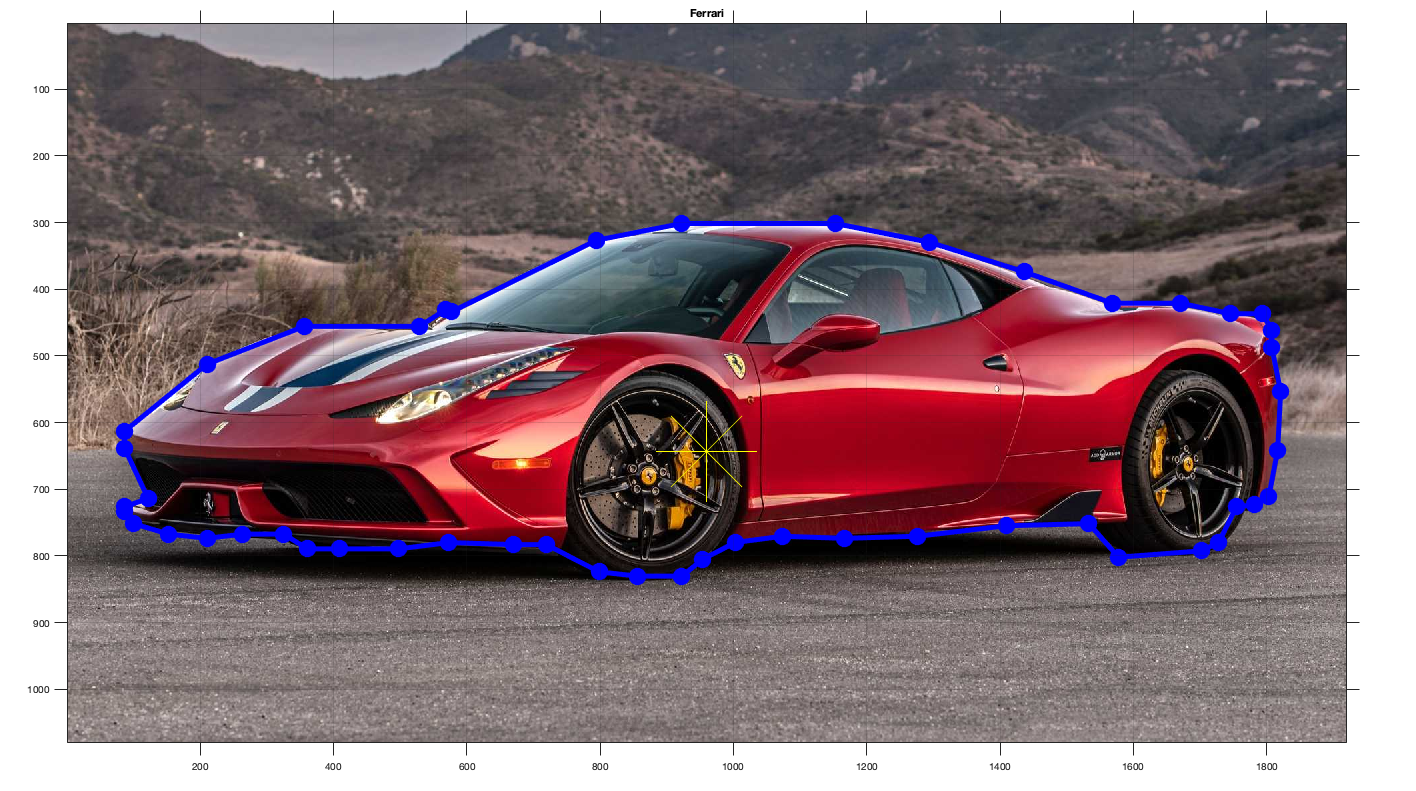

figure;
imshow(A)
axis on
hold on
xc = mean(x);
yc = mean(y);
plot (x,y,'b.-','MarkerSize',60, 'LineWidth',5)
grid on
plot (xc,yc,'y*','MarkerSize',100)
title('Ferrari');
hold off

y = -y;
xcentrati = x-xc;
ycentrati = y-yc;

E' stato utilizzato il seguente metodo per mettere in coda un punto "fittizio" uguale al primo punto,così facendo abbiamo ottenuto un poligono chiuso:

xcentrati = [xcentrati; xcentrati(1)];
ycentrati = [ycentrati; ycentrati(1)];

Visualizzazione dei punti:

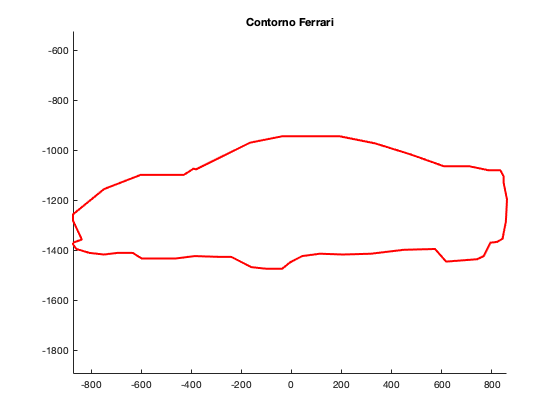

figure; 
hold on
plot (xcentrati,ycentrati, 'r', 'linewidth',2)
title ('Contorno Ferrari');
axis equal
hold off

**2**- **Curve Spline**

Risolvere un problema di interpolazione con curve parametriche normalmente corrisponde al risolvere due problemi di interpolazione ordinaria,rispettivamente sulle ascisse e sulle ordinate.

Si è reso necessaria la creazione del parametro t contenente i valori nell'intervallo. Creo il parametro tt da usare come griglia fitta di 500 punti,in modo da interpolare i 50 punti precedentemente acquisiti.

t = 1:length(xcentrati);
tt = linspace(t(1),t(end),500);

interpolazione x  e y con spline:

xsplineC = spline(t, [0 xcentrati' 0], tt);
ysplineC = spline(t, [0 ycentrati' 0], tt);

Costruzione della curva parametrica "miafotoS", basata sulle spline cubiche interpolanti,interpola i punti precedentemente calcolati con la funzione "spline":

miafotoS = [xsplineC; ysplineC];

Visualizzazione curva X delle spline,fornendo un opportuno xlim per visualizzare correttamente il tutto:

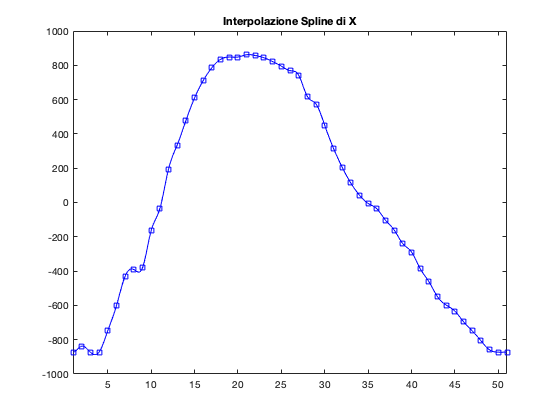

figure
plot(t,xcentrati,'bs',tt,xsplineC,'b')
xlim([1,51]);
title ('Interpolazione Spline di X')

Visualizzazione curva Y delle spline,fornendo un opportuno xlim per visualizzare correttamente il tutto:

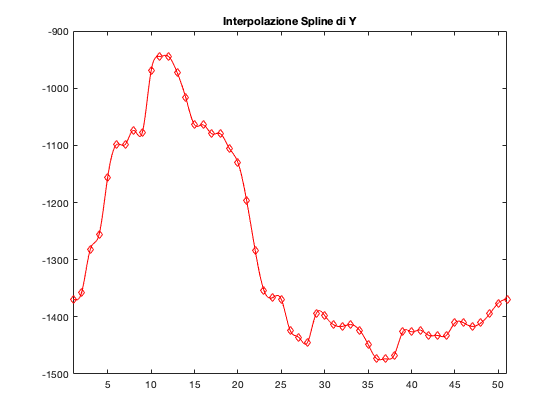

figure
plot(t,ycentrati,'rd',tt,ysplineC,'r')
xlim([1,51]);
title ('Interpolazione Spline di Y')

Visualizzazione della Spline Cubica:

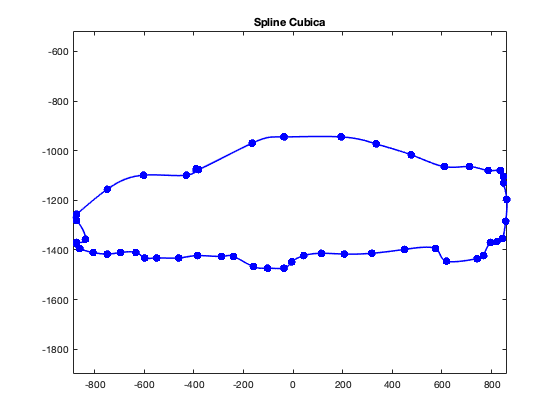

figure
plot(xcentrati,ycentrati,'b.',xsplineC,ysplineC,'b','MarkerSize',20, 'linewidth',1.5)
title ('Spline Cubica')
axis equal

**3**- **Curve di Hermite**

Qui utilizziamo il comando pchip per poter costruire la cubica che ha come parametri di ingresso il vettore delle ascisse e delle ordinate e la griglia fitta di valutazione e come parametro di uscita il vettore di valori che la cubica di Hermite assume sulla griglia di valutazione, che nel nostro caso è tt.

xH = pchip (t, xcentrati, tt);
yH = pchip (t, ycentrati, tt);

Costruzione della curva parametrica "miafotoC", basata sulle cubiche di Hermite,interpola i punti precedentemente calcolati con la funzione "pchip":

miafotoC = [xH; yH];

Visualizziamo le cubiche di Hermite sulle ascisse, fornendo un opportuno xlim per visualizzare correttamente il tutto:

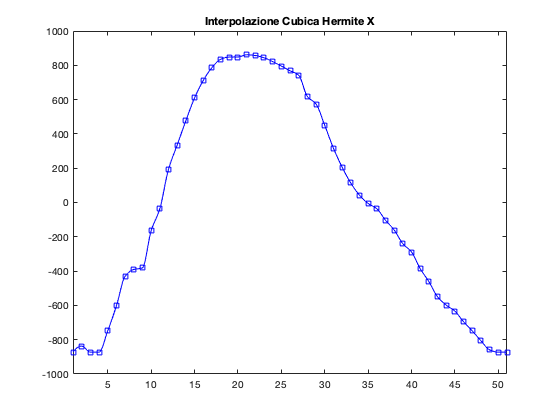

figure
plot (t, xcentrati,'bs', tt, xH, 'b')
xlim([1,51]);
title ('Interpolazione Cubica Hermite X')

Visualizziamo le cubiche di Hermite sulle ordinate, fornendo un opportuno xlim per visualizzare correttamente il tutto:

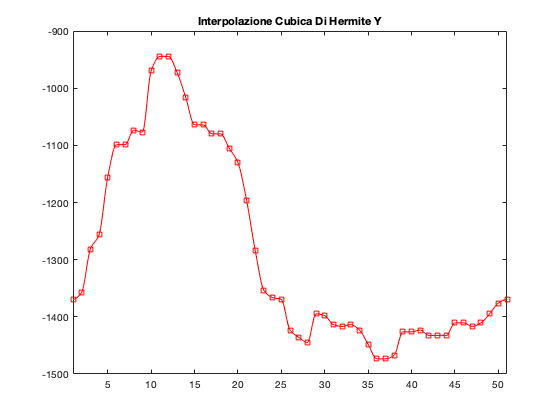

figure
plot (t, ycentrati,'rs', tt, yH, 'r')
xlim([1,51]);
title ('Interpolazione Cubica Di Hermite Y')

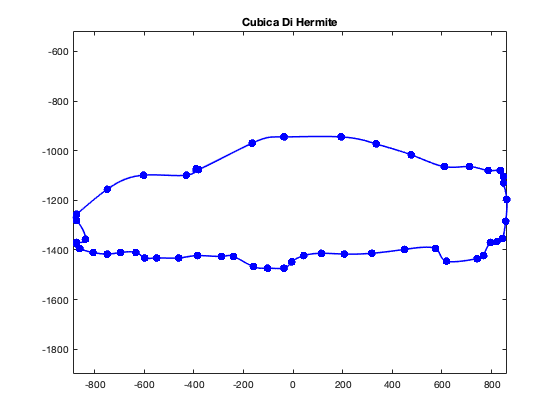

plot(xcentrati,ycentrati,'b.',xsplineC,ysplineC,'b','MarkerSize',20, 'linewidth',1.5)
axis equal
title ('Cubica Di Hermite')

Proseguiamo al calcolo del vettore delle distanze e la conseguente norma infinito:

vdistanze = sqrt ( (xsplineC-xH).^2 + (ysplineC - yH).^2);
norm (vdistanze,Inf)

ans =   21.927017566481886


**4**- **Fill miafotoS e calcolo Perimetro e Area**

Si è utilizzata la function matlab 'fill',che permette di riempire con un colore,in questo caso rosso come da traccia, la miafotoS. Tramite la function LunghezzaPoligonale e AreaPoligono calcolo rispettivamente il perimetro  e l'area del poligono che si viene a formare,dando in input i punti di ascissa x e i punti di ordinata y della cubica di Spline.

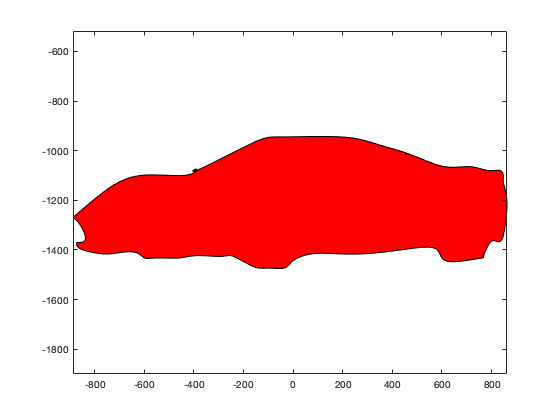

fill(xsplineC, ysplineC,'r')
axis equal

PerimetroS = Lunghezza (xsplineC, ysplineC)

PerimetroS =      4.158680203736151e+03


AreaS = AreaPoligono (xsplineC, ysplineC)

AreaS =      6.616700968571985e+05


**5**- **Fill miafotoC e calcolo Perimetro e Area **

Si è utilizzata la function matlab 'fill',che permette di riempire con un colore, la miafotoC. Allo stesso modo del punto precedente tramite le function LunghezzaPoligonale e AreaPoligono calcolo rispettivamente il perimetro  e l'area del poligono che si viene a formare,dando in input i punti di ascissa x e i punti di ordinata y della cubica di Hermite:

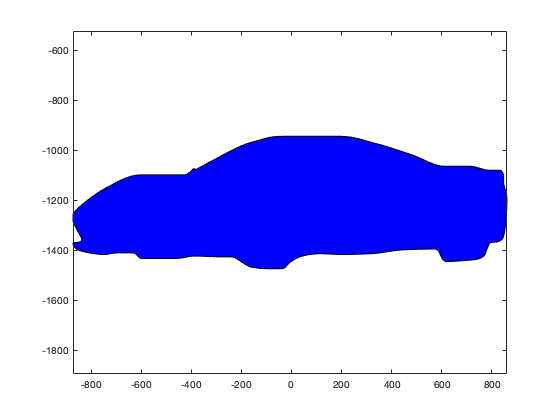

fill(xH, yH,'b')
axis equal

PerimetroC = Lunghezza (xH,yH)

PerimetroC =      4.089664892931587e+03


AreaC = AreaPoligono (xH, yH) 

AreaC =      6.627339934259979e+05


Si sono poi calcolati,come richiesto dalla traccia,le differenze tra i 2 perimetri e le 2 aree e si è proceduto alla visualizzazione dei risultati:

DiffPerimetro = PerimetroS-PerimetroC

DiffPerimetro =   69.015310804563796


DiffArea = AreaS-AreaC

DiffArea =     -1.063896568799391e+03


**6**- **Costruzione della matrice D delle distanze e visualizzazione**

Costruisco la matrice D delle distanze tra i 51 punti tramite due cicli for innestati. Proseguirò con il visualizzare le prime 8 righe e le prime 8 colonne della nostra matrice:

D=zeros

D =      0


for i = 1:51
    for j = i+1:51
        D(i,j)= sqrt(((xcentrati(j)-xcentrati(i)).^2)+((ycentrati(j)-ycentrati(i)).^2));
    end
end

Visualizzazione del blocco di D che coinvolge le distanze tra i primi 8 punti:

D1=D(1:8,1:8)

D1 = 	1.0e+02 *

                   0   0.375659496132000   0.881632653061224   1.133527696793003   2.473609626289931   3.822970798488227   5.186908429924138   5.658008378664843
                   0                   0   0.834456287818421   1.067930282217029   2.200847388606725   3.487685882720332   4.819917808722850   5.291064868736544
                   0                   0                   0   0.251895043731779   1.766544505906440   3.258479032236626   4.786083883286012   5.250855254058823
                   0                   0                   0                   0   1.596752790458973   3.124275208310108   4.695743701649989   5.156354201051292
                   0                   0                   0                   0                   0   1.566062624520425   3.235283734113332   3.675735382282753
                   0                   0                   0                   0                   0                   0   1.725345622119817   2.138390317219060
                 

**7**- **Determinazione e visualizzazione segmento tra i punti più lontani**

Determinerò il valore massimo della matrice e il corrispettivo indice tramite l'uso della function 'max' in modo da poter determinare la distanza tra i 2 punti più lontani lungo il bordo dell'oggetto:

[max_dist, pos_idx]=max(D(:));

[i,j]=ind2sub(size(D),pos_idx);
figure (9);

Visualizzo il grafico con un segmento che unisce i punti più distanti da uno rispetto a un altro sul bordo:

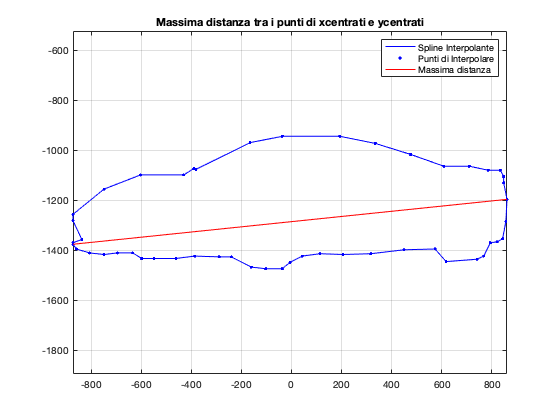

plot(xcentrati,ycentrati,'b');
axis on
axis equal
hold on
grid on
plot(xcentrati,ycentrati,'.b','LineWidth',5);
plot([xcentrati(j) xcentrati(i)], [ycentrati(j) ycentrati(i)],'r')
title('Massima distanza tra i punti di xcentrati e ycentrati');
legend('Spline Interpolante', 'Punti di Interpolare', 'Massima distanza')
hold off

**8**- **Rotazione poligoni "miafotoS" e "miafotoC" e loro visualizzazione.**

Si è proceduto alla creazione randomica del angolo theta mediante l'utilizzo della function "rand",in modo che restituisca un valore compreso tra 10 e 80 gradi.

theta = 10+rand(1,1)*(80-10)

theta =   18.889077140545425


R=[cosd(theta) -sind(theta); sind(theta) cosd(theta)];
Orario = R'*miafotoS;
AntiOrario= R*miafotoC;

Visualizzazione del poligono miafotoS ruotato in senso orario:

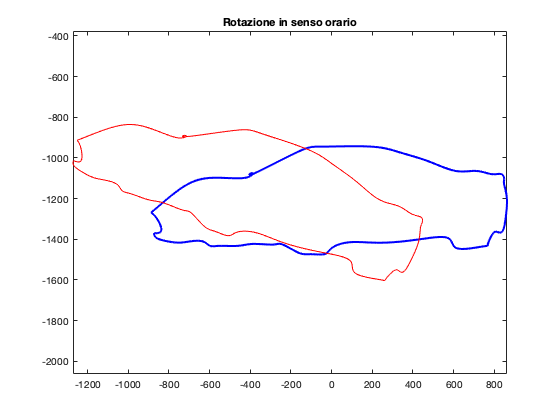

figure
plot(miafotoS(1,:),miafotoS(2,:),'b-','LineWidth',2);
axis on
axis equal
hold on
plot(Orario(1,:),Orario(2,:),"Color",'r');
title('Rotazione in senso orario')

Visualizzazione del poligono miafotoC ruotato in senso antiorario:

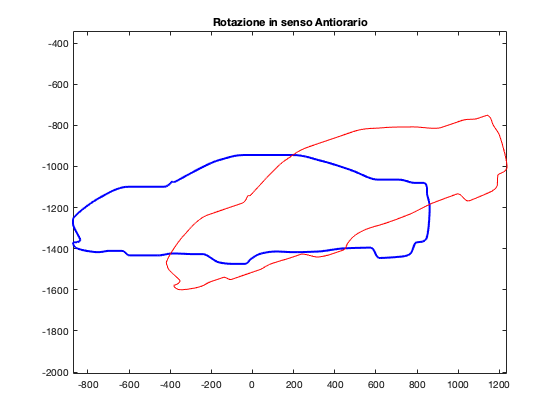

figure
plot(miafotoC(1,:),miafotoC(2,:),'b-','LineWidth',2);
axis on
axis equal
hold on
plot(AntiOrario(1,:),AntiOrario(2,:),"Color",'r');
title('Rotazione in senso Antiorario')

**9**- **Costruzione miafotoAppr5 mediante minimi quadrati  e visualizzazione grafici**

Abbiamo costruito a partire dai vertici del poligono ottenuti nel 1° punto la curva parametrica,basata sull'approssimazione dei minimi quadrati con polinomi di grado 5 e la abbiamo chiamata "miafotoAppr5".

Si è proceduto approssimando i punti di ascissa xCentrati e i punti di ordinata yCentrati utilizzando da prima la function polyfit e subito dopo la function polyval che prende in input il risultato di polyfit.

Polyval esegue la valutazione dei punti sulla griglia, mentre polyfit si occupa di calcolare i coefficienti del polinomio(di grado 5 nel nostro caso) approssimati nel senso dei minimi quadrati:

figure
xpoly = polyfit(t,xcentrati,5);
ypoly = polyfit(t,ycentrati,5);
xMQ = polyval(xpoly,tt);
yMQ = polyval(ypoly,tt);
miafotoAppr5 = [xMQ, yMQ];

Visualizzazione in blu dell'approssimazione dei punti delle ascisse mediante il metodo dei minimi quadrati:

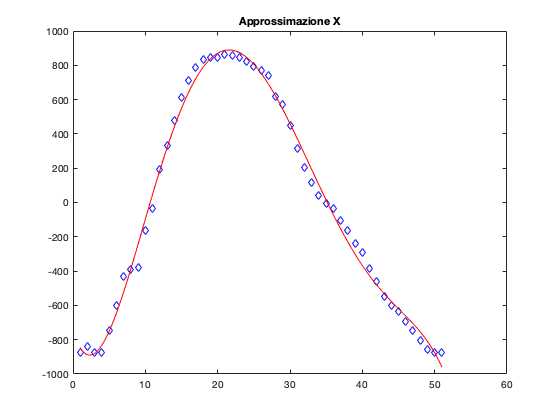

plot(t,xcentrati,'bd',tt,xMQ,'r')
title('Approssimazione X')

Visualizzazione in blu dell'approssimazione dei punti delle ordinate mediante il metodo dei minimi quadrati:

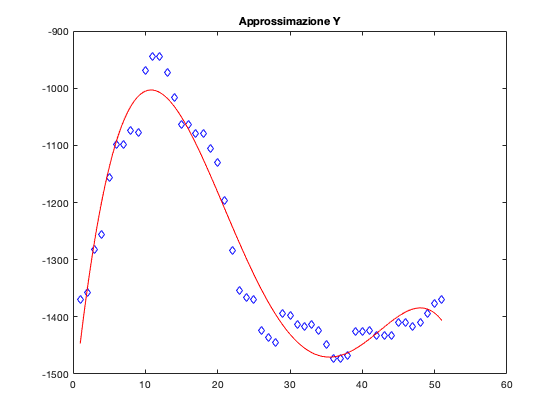

figure 
plot(t,ycentrati,'bd',tt,yMQ,'r')
title('Approssimazione Y')

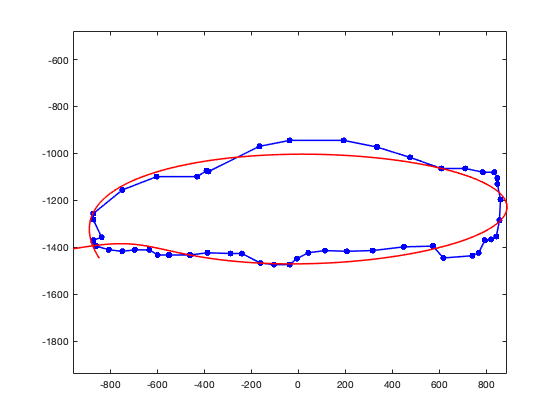

plot(xcentrati,ycentrati,'b.-',xMQ,yMQ,'r','markersize',15,'linewidth',1.5)
axis equal 